# Prep neuromaps images for CANlab tools

Purpose: Prep neuromaps images for CANlab tools, attach metadata

These images are part of the Neuromaps toolbox:

Hansen et al. "Mapping neurotransmitter systems to the structural and functional

organization of the human neocortex"

https://www.biorxiv.org/content/10.1101/2021.10.28.466336v2

https://www.biorxiv.org/content/10.1101/2021.10.28.466336v2.full.pdf

Markello et al. "neuromaps: structural and functional interpretation of brain maps"

https://www.biorxiv.org/content/10.1101/2022.01.06.475081v1

**The specifc images here come from the Hansen repository:**

**NIFTI images for PET transmitter images from Hansen 2021 preprint:**

[https://github.com/netneurolab/hansen_receptors/tree/main/data/PET_nifti_images](https://github.com/netneurolab/hansen_receptors/tree/main/data/PET_nifti_images)

**Email from Justine Hansen:**

A long-form description of all the included annotations and their full references doesn't yet exist (but it should and will🙂).

One quick way to get access to all the receptor maps on neuromaps is to do `available_annotations(tags='receptors')`�. These are study-specific and not all of them made it into the [Hansen 2021 preprint](https://www.biorxiv.org/content/10.1101/2021.10.28.466336v2). All the images used in Hansen 2021 are also on that preprint's [github](https://github.com/netneurolab/hansen_receptors/tree/main/data/PET_nifti_images). That repo also has [supplementary table S3](https://github.com/netneurolab/hansen_receptors/tree/main/manuscript) with PET tracer name, receptor target, and links to all the papers that originally publish the data (except for a few exceptions that were shared before publication). The list of receptors that are used in the main analyses in Hansen 2021 (including those that get combined into a single receptor map post-parcellation) can be found in Table 1 in the preprint and in [this script](https://github.com/netneurolab/hansen_receptors/blob/main/code/make_receptor_matrix.py) (which also outlines how I combine some maps).

## Load and prep maps

- Some are zipped. unzip to make sure we have all of them. 

- There are  39 images. Some are duplicates that were averaged in some way in the preprint. (sample size weighted?)

- They have different voxel sizes/spaces.  So we need to resample to a common mask.

basedir = '/Users/torwager/Documents/GitHub/hansen_receptors';
datadir = fullfile(basedir, 'data', 'PET_nifti_images');
metadatadir = fullfile(basedir, 'manuscript');
cd(datadir)

!gunzip *gz
imgs = filenames('*nii')

obj = fmri_data(imgs, which('brainmask_canlab.nii'), 'sample2mask');

## Examine maps

- Do any look distorted? In wrong space?  Messed up by resampling? masking?

- Scale?

plot(obj)


dd = descriptives(obj, 'plotcoverage');

We can see that the images are masked differently. For some, a tight gray-matter mask has been applied, so that medial PFC voxels and others are masked out.  Some voxels may be missing due to functional thresholding as well (?)

% show coverage for each individually
for i = 1:size(obj.dat, 2)
    
    obj1 = get_wh_image(obj, i);
    dd = descriptives(obj1, 'plotcoverage');
    drawnow
    
end


### Rescale and examine

 
Source: Info about image source here
 
 
Summary of dataset
______________________________________________________
Images:   1	Nonempty:   1	Complete:   1
  Images missing >50% of voxels:   0	
Number of unique values in dataset: 128121  Bit rate: 16.97 bits
  Images missing >10% of voxels:   0	
Voxels: 576094	Nonempty (1+ images have valid data): 193186	Complete  (all images have data): 193186
Unique data values: 128120
 
Min: 0.000	Max: 161.344	Mean: 27.678	Std: 14.791
 
    Percentiles     Values 
    ___________    ________

        0.1        0.023975
        0.5          0.1264
          1         0.24698
          5          1.3693
         25          19.475
         50          29.471
         75          36.122
         95              51
         99          62.187


Setting up fmridisplay objects


Grouping contiguous voxels:   1 regions
sagittal montage: 4889 voxels displayed, 188297 not displayed on these slices


axial montage: 30485 voxels displayed, 162701 not displayed on these slices


Grouping contiguous voxels:   1 regions
sagittal montage: 4889 voxels displayed, 188297 not displayed on these slices


axial montage: 30485 voxels displayed, 162701 not displayed on these slices


 
Source: Info about image source here
 
 
Summary of dataset
______________________________________________________
Images:   1	Nonempty:   1	Complete:   1
  Images missing >50% of voxels:   0	
Number of unique values in dataset: 17331  Bit rate: 14.08 bits
  Images missing >10% of voxels:   0	
Voxels: 576094	Nonempty (1+ images have valid data): 491773	Complete  (all images have data): 491773
Unique data values: 17330
 
Min: 0.003	Max: 100.000	Mean: 22.455	Std: 15.311
 
    Percentiles     Values  
    ___________    _________

        0.1        0.0091556
        0.5         0.039674
          1         0.079348
          5          0.46693
         25           9.8086
         50           22.141
         75           32.612
         95           48.735
         99         

Setting up fmridisplay objects


Grouping contiguous voxels:   1 regions
sagittal montage: 12165 voxels displayed, 479608 not displayed on these slices


axial montage: 79149 voxels displayed, 412624 not displayed on these slices


Grouping contiguous voxels:   1 regions
sagittal montage: 12165 voxels displayed, 479608 not displayed on these slices


axial montage: 79149 voxels displayed, 412624 not displayed on these slices


 
Source: Info about image source here
 
 
Summary of dataset
______________________________________________________
Images:   1	Nonempty:   1	Complete:   1
  Images missing >50% of voxels:   0	
Number of unique values in dataset: 146832  Bit rate: 17.16 bits
  Images missing >10% of voxels:   0	
Voxels: 576094	Nonempty (1+ images have valid data): 212320	Complete  (all images have data): 212320
Unique data values: 146831
 
Min: 0.000	Max: 54.847	Mean: 16.217	Std: 8.185
 
    Percentiles     Values 
    ___________    ________

        0.1        0.011755
        0.5        0.060675
          1         0.12279
          5          0.6107
         25          11.272
         50          19.317
         75          21.787
         95          24.368
         99          32.814
  

Setting up fmridisplay objects


Grouping contiguous voxels:   9 regions
sagittal montage: 5025 voxels displayed, 207295 not displayed on these slices


axial montage: 32873 voxels displayed, 179447 not displayed on these slices


Grouping contiguous voxels:   9 regions
sagittal montage: 5025 voxels displayed, 207295 not displayed on these slices


axial montage: 32873 voxels displayed, 179447 not displayed on these slices


 
Source: Info about image source here
 
 
Summary of dataset
______________________________________________________
Images:   1	Nonempty:   1	Complete:   1
  Images missing >50% of voxels:   0	
Number of unique values in dataset: 16206  Bit rate: 13.98 bits
  Images missing >10% of voxels:   0	
Voxels: 576094	Nonempty (1+ images have valid data): 378800	Complete  (all images have data): 378800
Unique data values: 16205
 
Min: 0.003	Max: 100.000	Mean: 30.185	Std: 18.100
 
    Percentiles     Values 
    ___________    ________

        0.1        0.036622
        0.5         0.18006
          1         0.35096
          5          2.0569
         25          15.015
         50          30.781
         75           43.98
         95          58.769
         99          70.992
  

Setting up fmridisplay objects


Grouping contiguous voxels:   7 regions
sagittal montage: 9799 voxels displayed, 369001 not displayed on these slices


axial montage: 61772 voxels displayed, 317028 not displayed on these slices


Grouping contiguous voxels:   7 regions
sagittal montage: 9799 voxels displayed, 369001 not displayed on these slices


axial montage: 61772 voxels displayed, 317028 not displayed on these slices


 
Source: Info about image source here
 
 
Summary of dataset
______________________________________________________
Images:   1	Nonempty:   1	Complete:   1
  Images missing >50% of voxels:   0	
Number of unique values in dataset: 570149  Bit rate: 19.12 bits
  Images missing >10% of voxels:   0	
Voxels: 576094	Nonempty (1+ images have valid data): 576094	Complete  (all images have data): 576094
Unique data values: 570149
 
Min: -0.693	Max: 3.208	Mean: 0.594	Std: 0.446
 
    Percentiles     Values 
    ___________    ________

        0.1        -0.53416
        0.5        -0.38817
          1        -0.32729
          5        -0.14662
         25         0.22465
         50         0.64841
         75         0.94041
         95          1.2299
         99          1.4995
   

Setting up fmridisplay objects


Grouping contiguous voxels:   1 regions
sagittal montage: 16001 voxels displayed, 560093 not displayed on these slices


axial montage: 86399 voxels displayed, 489695 not displayed on these slices


Grouping contiguous voxels:   1 regions
sagittal montage: 16001 voxels displayed, 560093 not displayed on these slices


axial montage: 86399 voxels displayed, 489695 not displayed on these slices


 
Source: Info about image source here
 
 
Summary of dataset
______________________________________________________
Images:   1	Nonempty:   1	Complete:   1
  Images missing >50% of voxels:   0	
Number of unique values in dataset: 24311  Bit rate: 14.57 bits
  Images missing >10% of voxels:   0	
Voxels: 576094	Nonempty (1+ images have valid data): 428238	Complete  (all images have data): 428238
Unique data values: 24310
 
Min: 0.006	Max: 100.000	Mean: 46.966	Std: 24.736
 
    Percentiles    Values 
    ___________    _______

        0.1        0.10681
        0.5        0.43336
          1        0.79958
          5         3.9216
         25         27.235
         50         50.758
         75         67.211
         95         82.247
         99          89.23
       99.5  

Setting up fmridisplay objects


Grouping contiguous voxels:   1 regions
sagittal montage: 9451 voxels displayed, 418787 not displayed on these slices


axial montage: 69011 voxels displayed, 359227 not displayed on these slices


Grouping contiguous voxels:   1 regions
sagittal montage: 9451 voxels displayed, 418787 not displayed on these slices


axial montage: 69011 voxels displayed, 359227 not displayed on these slices


 
Source: Info about image source here
 
 
Summary of dataset
______________________________________________________
Images:   1	Nonempty:   1	Complete:   1
  Images missing >50% of voxels:   0	
Number of unique values in dataset: 140278  Bit rate: 17.10 bits
  Images missing >10% of voxels:   0	
Voxels: 576094	Nonempty (1+ images have valid data): 205577	Complete  (all images have data): 205577
Unique data values: 140277
 
Min: 0.000	Max: 108.520	Mean: 41.037	Std: 21.530
 
    Percentiles     Values 
    ___________    ________

        0.1        0.048196
        0.5          0.2304
          1          0.4483
          5          1.8674
         25          19.531
         50          51.268
         75          57.209
         95          62.391
         99          65.992


Setting up fmridisplay objects


Grouping contiguous voxels:  17 regions
sagittal montage: 4733 voxels displayed, 200844 not displayed on these slices


axial montage: 31721 voxels displayed, 173856 not displayed on these slices


Grouping contiguous voxels:  17 regions
sagittal montage: 4733 voxels displayed, 200844 not displayed on these slices


axial montage: 31721 voxels displayed, 173856 not displayed on these slices


 
Source: Info about image source here
 
 
Summary of dataset
______________________________________________________
Images:   1	Nonempty:   1	Complete:   1
  Images missing >50% of voxels:   0	
Number of unique values in dataset: 566993  Bit rate: 19.11 bits
  Images missing >10% of voxels:   0	
Voxels: 576094	Nonempty (1+ images have valid data): 576094	Complete  (all images have data): 576094
Unique data values: 566993
 
Min: 0.001	Max: 218.752	Mean: 52.115	Std: 22.911
 
    Percentiles    Values
    ___________    ______

        0.1        9.4012
        0.5        12.737
          1        14.378
          5        19.808
         25        31.921
         50        52.479
         75        68.741
         95        88.271
         99        105.39
       99.5        117

Setting up fmridisplay objects


Grouping contiguous voxels:   1 regions
sagittal montage: 16001 voxels displayed, 560093 not displayed on these slices


axial montage: 86399 voxels displayed, 489695 not displayed on these slices


Grouping contiguous voxels:   1 regions
sagittal montage: 16001 voxels displayed, 560093 not displayed on these slices


axial montage: 86399 voxels displayed, 489695 not displayed on these slices


 
Source: Info about image source here
 
 
Summary of dataset
______________________________________________________
Images:   1	Nonempty:   1	Complete:   1
  Images missing >50% of voxels:   0	
Number of unique values in dataset: 143436  Bit rate: 17.13 bits
  Images missing >10% of voxels:   0	
Voxels: 576094	Nonempty (1+ images have valid data): 208863	Complete  (all images have data): 208863
Unique data values: 143435
 
Min: 0.000	Max: 24.594	Mean: 2.007	Std: 1.225
 
    Percentiles     Values 
    ___________    ________

        0.1        0.003699
        0.5        0.018225
          1        0.036671
          5         0.16189
         25          1.5603
         50          2.0865
         75           2.395
         95          2.8988
         99          7.8197
   

Setting up fmridisplay objects


Grouping contiguous voxels:   2 regions
sagittal montage: 4700 voxels displayed, 204163 not displayed on these slices


axial montage: 32555 voxels displayed, 176308 not displayed on these slices


Grouping contiguous voxels:   2 regions
sagittal montage: 4700 voxels displayed, 204163 not displayed on these slices


axial montage: 32555 voxels displayed, 176308 not displayed on these slices


 
Source: Info about image source here
 
 
Summary of dataset
______________________________________________________
Images:   1	Nonempty:   1	Complete:   1
  Images missing >50% of voxels:   0	
Number of unique values in dataset: 570654  Bit rate: 19.12 bits
  Images missing >10% of voxels:   0	
Voxels: 576094	Nonempty (1+ images have valid data): 576094	Complete  (all images have data): 576094
Unique data values: 570654
 
Min: -0.951	Max: 1.610	Mean: 0.266	Std: 0.291
 
    Percentiles     Values 
    ___________    ________

        0.1        -0.65492
        0.5        -0.51587
          1        -0.45429
          5        -0.27144
         25        0.083585
         50         0.30563
         75         0.48683
         95         0.63319
         99          0.8901
   

Setting up fmridisplay objects


Grouping contiguous voxels:   1 regions
sagittal montage: 16001 voxels displayed, 560093 not displayed on these slices


axial montage: 86399 voxels displayed, 489695 not displayed on these slices


Grouping contiguous voxels:   1 regions
sagittal montage: 16001 voxels displayed, 560093 not displayed on these slices


axial montage: 86399 voxels displayed, 489695 not displayed on these slices


 
Source: Info about image source here
 
 
Summary of dataset
______________________________________________________
Images:   1	Nonempty:   1	Complete:   1
  Images missing >50% of voxels:   0	
Number of unique values in dataset: 151510  Bit rate: 17.21 bits
  Images missing >10% of voxels:   0	
Voxels: 576094	Nonempty (1+ images have valid data): 216680	Complete  (all images have data): 216680
Unique data values: 151509
 
Min: 0.000	Max: 78.579	Mean: 5.330	Std: 4.423
 
    Percentiles     Values 
    ___________    ________

        0.1        0.019488
        0.5        0.098608
          1         0.18799
          5         0.66708
         25          3.3738
         50          4.2531
         75           5.815
         95          14.191
         99          24.444
   

Setting up fmridisplay objects


Grouping contiguous voxels:   2 regions
sagittal montage: 5318 voxels displayed, 211362 not displayed on these slices


axial montage: 32973 voxels displayed, 183707 not displayed on these slices


Grouping contiguous voxels:   2 regions
sagittal montage: 5318 voxels displayed, 211362 not displayed on these slices


axial montage: 32973 voxels displayed, 183707 not displayed on these slices


 
Source: Info about image source here
 
 
Summary of dataset
______________________________________________________
Images:   1	Nonempty:   1	Complete:   1
  Images missing >50% of voxels:   0	
Number of unique values in dataset: 8754  Bit rate: 13.10 bits
  Images missing >10% of voxels:   0	
Voxels: 576094	Nonempty (1+ images have valid data): 329147	Complete  (all images have data): 329147
Unique data values: 8753
 
Min: 0.003	Max: 100.000	Mean: 8.675	Std: 10.142
 
    Percentiles     Values 
    ___________    ________

        0.1        0.012207
        0.5        0.067141
          1         0.12513
          5         0.61647
         25          2.9695
         50          5.8626
         75          10.276
         95          27.674
         99          55.605
     

Setting up fmridisplay objects


Grouping contiguous voxels:   8 regions
sagittal montage: 9639 voxels displayed, 319508 not displayed on these slices


axial montage: 55142 voxels displayed, 274005 not displayed on these slices


Grouping contiguous voxels:   8 regions
sagittal montage: 9639 voxels displayed, 319508 not displayed on these slices


axial montage: 55142 voxels displayed, 274005 not displayed on these slices


 
Source: Info about image source here
 
 
Summary of dataset
______________________________________________________
Images:   1	Nonempty:   1	Complete:   1
  Images missing >50% of voxels:   0	
Number of unique values in dataset: 8553  Bit rate: 13.06 bits
  Images missing >10% of voxels:   0	
Voxels: 576094	Nonempty (1+ images have valid data): 375835	Complete  (all images have data): 375835
Unique data values: 8552
 
Min: 0.003	Max: 97.320	Mean: 8.977	Std: 8.539
 
    Percentiles     Values 
    ___________    ________

        0.1        0.023761
        0.5         0.11286
          1         0.21088
          5         0.99498
         25          4.0928
         50          7.2886
         75          10.927
         95          23.338
         99          47.391
       

Setting up fmridisplay objects


Grouping contiguous voxels:   2 regions
sagittal montage: 9666 voxels displayed, 366169 not displayed on these slices


axial montage: 58234 voxels displayed, 317601 not displayed on these slices


Grouping contiguous voxels:   2 regions
sagittal montage: 9666 voxels displayed, 366169 not displayed on these slices


axial montage: 58234 voxels displayed, 317601 not displayed on these slices


 
Source: Info about image source here
 
 
Summary of dataset
______________________________________________________
Images:   1	Nonempty:   1	Complete:   1
  Images missing >50% of voxels:   0	
Number of unique values in dataset: 553324  Bit rate: 19.08 bits
  Images missing >10% of voxels:   0	
Voxels: 576094	Nonempty (1+ images have valid data): 576094	Complete  (all images have data): 576094
Unique data values: 553324
 
Min: 1.046	Max: 31.450	Mean: 9.870	Std: 2.802
 
    Percentiles    Values
    ___________    ______

        0.1        1.8007
        0.5        2.3137
          1        2.6545
          5        4.6635
         25        8.8375
         50        10.035
         75        11.023
         95        14.168
         99        18.291
       99.5         22.37

Setting up fmridisplay objects


Grouping contiguous voxels:   1 regions
sagittal montage: 16001 voxels displayed, 560093 not displayed on these slices


axial montage: 86399 voxels displayed, 489695 not displayed on these slices


Grouping contiguous voxels:   1 regions
sagittal montage: 16001 voxels displayed, 560093 not displayed on these slices


axial montage: 86399 voxels displayed, 489695 not displayed on these slices


 
Source: Info about image source here
 
 
Summary of dataset
______________________________________________________
Images:   1	Nonempty:   1	Complete:   1
  Images missing >50% of voxels:   0	
Number of unique values in dataset: 29726  Bit rate: 14.86 bits
  Images missing >10% of voxels:   0	
Voxels: 576094	Nonempty (1+ images have valid data): 576094	Complete  (all images have data): 576094
Unique data values: 29726
 
Min: 0.360	Max: 13.670	Mean: 7.479	Std: 2.559
 
    Percentiles    Values 
    ___________    _______

        0.1        0.81544
        0.5         1.5728
          1              2
          5          3.106
         25         5.5891
         50         7.5974
         75         9.4952
         95         11.433
         99         12.405
       99.5     

Setting up fmridisplay objects


Grouping contiguous voxels:   1 regions
sagittal montage: 16001 voxels displayed, 560093 not displayed on these slices


axial montage: 86399 voxels displayed, 489695 not displayed on these slices


Grouping contiguous voxels:   1 regions
sagittal montage: 16001 voxels displayed, 560093 not displayed on these slices


axial montage: 86399 voxels displayed, 489695 not displayed on these slices


 
Source: Info about image source here
 
 
Summary of dataset
______________________________________________________
Images:   1	Nonempty:   1	Complete:   1
  Images missing >50% of voxels:   0	
Number of unique values in dataset: 547976  Bit rate: 19.06 bits
  Images missing >10% of voxels:   0	
Voxels: 576094	Nonempty (1+ images have valid data): 576094	Complete  (all images have data): 576094
Unique data values: 547976
 
Min: 0.143	Max: 2.107	Mean: 1.226	Std: 0.190
 
    Percentiles    Values 
    ___________    _______

        0.1        0.48666
        0.5        0.69644
          1        0.74375
          5        0.88358
         25         1.1041
         50         1.2397
         75         1.3654
         95          1.505
         99         1.5929
       99.5    

Setting up fmridisplay objects


Grouping contiguous voxels:   1 regions
sagittal montage: 16001 voxels displayed, 560093 not displayed on these slices


axial montage: 86399 voxels displayed, 489695 not displayed on these slices


Grouping contiguous voxels:   1 regions
sagittal montage: 16001 voxels displayed, 560093 not displayed on these slices


axial montage: 86399 voxels displayed, 489695 not displayed on these slices


 
Source: Info about image source here
 
 
Summary of dataset
______________________________________________________
Images:   1	Nonempty:   1	Complete:   1
  Images missing >50% of voxels:   0	
Number of unique values in dataset: 10030  Bit rate: 13.29 bits
  Images missing >10% of voxels:   0	
Voxels: 576094	Nonempty (1+ images have valid data): 576050	Complete  (all images have data): 576050
Unique data values: 10029
 
Min: -0.003	Max: 100.000	Mean: 9.587	Std: 10.158
 
    Percentiles    Values
    ___________    ______

        0.1        -0.003
        0.5        -0.003
          1        -0.003
          5        -0.003
         25         0.501
         50         8.585
         75        15.165
         95        22.929
         99        50.821
       99.5        69.03

Setting up fmridisplay objects


Grouping contiguous voxels:   1 regions
sagittal montage: 16001 voxels displayed, 560049 not displayed on these slices


axial montage: 86399 voxels displayed, 489651 not displayed on these slices


Grouping contiguous voxels:   1 regions
sagittal montage: 16001 voxels displayed, 560049 not displayed on these slices


axial montage: 86399 voxels displayed, 489651 not displayed on these slices


 
Source: Info about image source here
 
 
Summary of dataset
______________________________________________________
Images:   1	Nonempty:   1	Complete:   1
  Images missing >50% of voxels:   0	
Number of unique values in dataset: 19995  Bit rate: 14.29 bits
  Images missing >10% of voxels:   0	
Voxels: 576094	Nonempty (1+ images have valid data): 575884	Complete  (all images have data): 575884
Unique data values: 19994
 
Min: -0.218	Max: 20.485	Mean: 1.088	Std: 1.922
 
    Percentiles     Values 
    ___________    ________

        0.1        -0.19418
        0.5         -0.1685
          1        -0.14156
          5        -0.02944
         25          0.4297
         50         0.71722
         75          1.0473
         95          3.1081
         99          12.186
    

Setting up fmridisplay objects


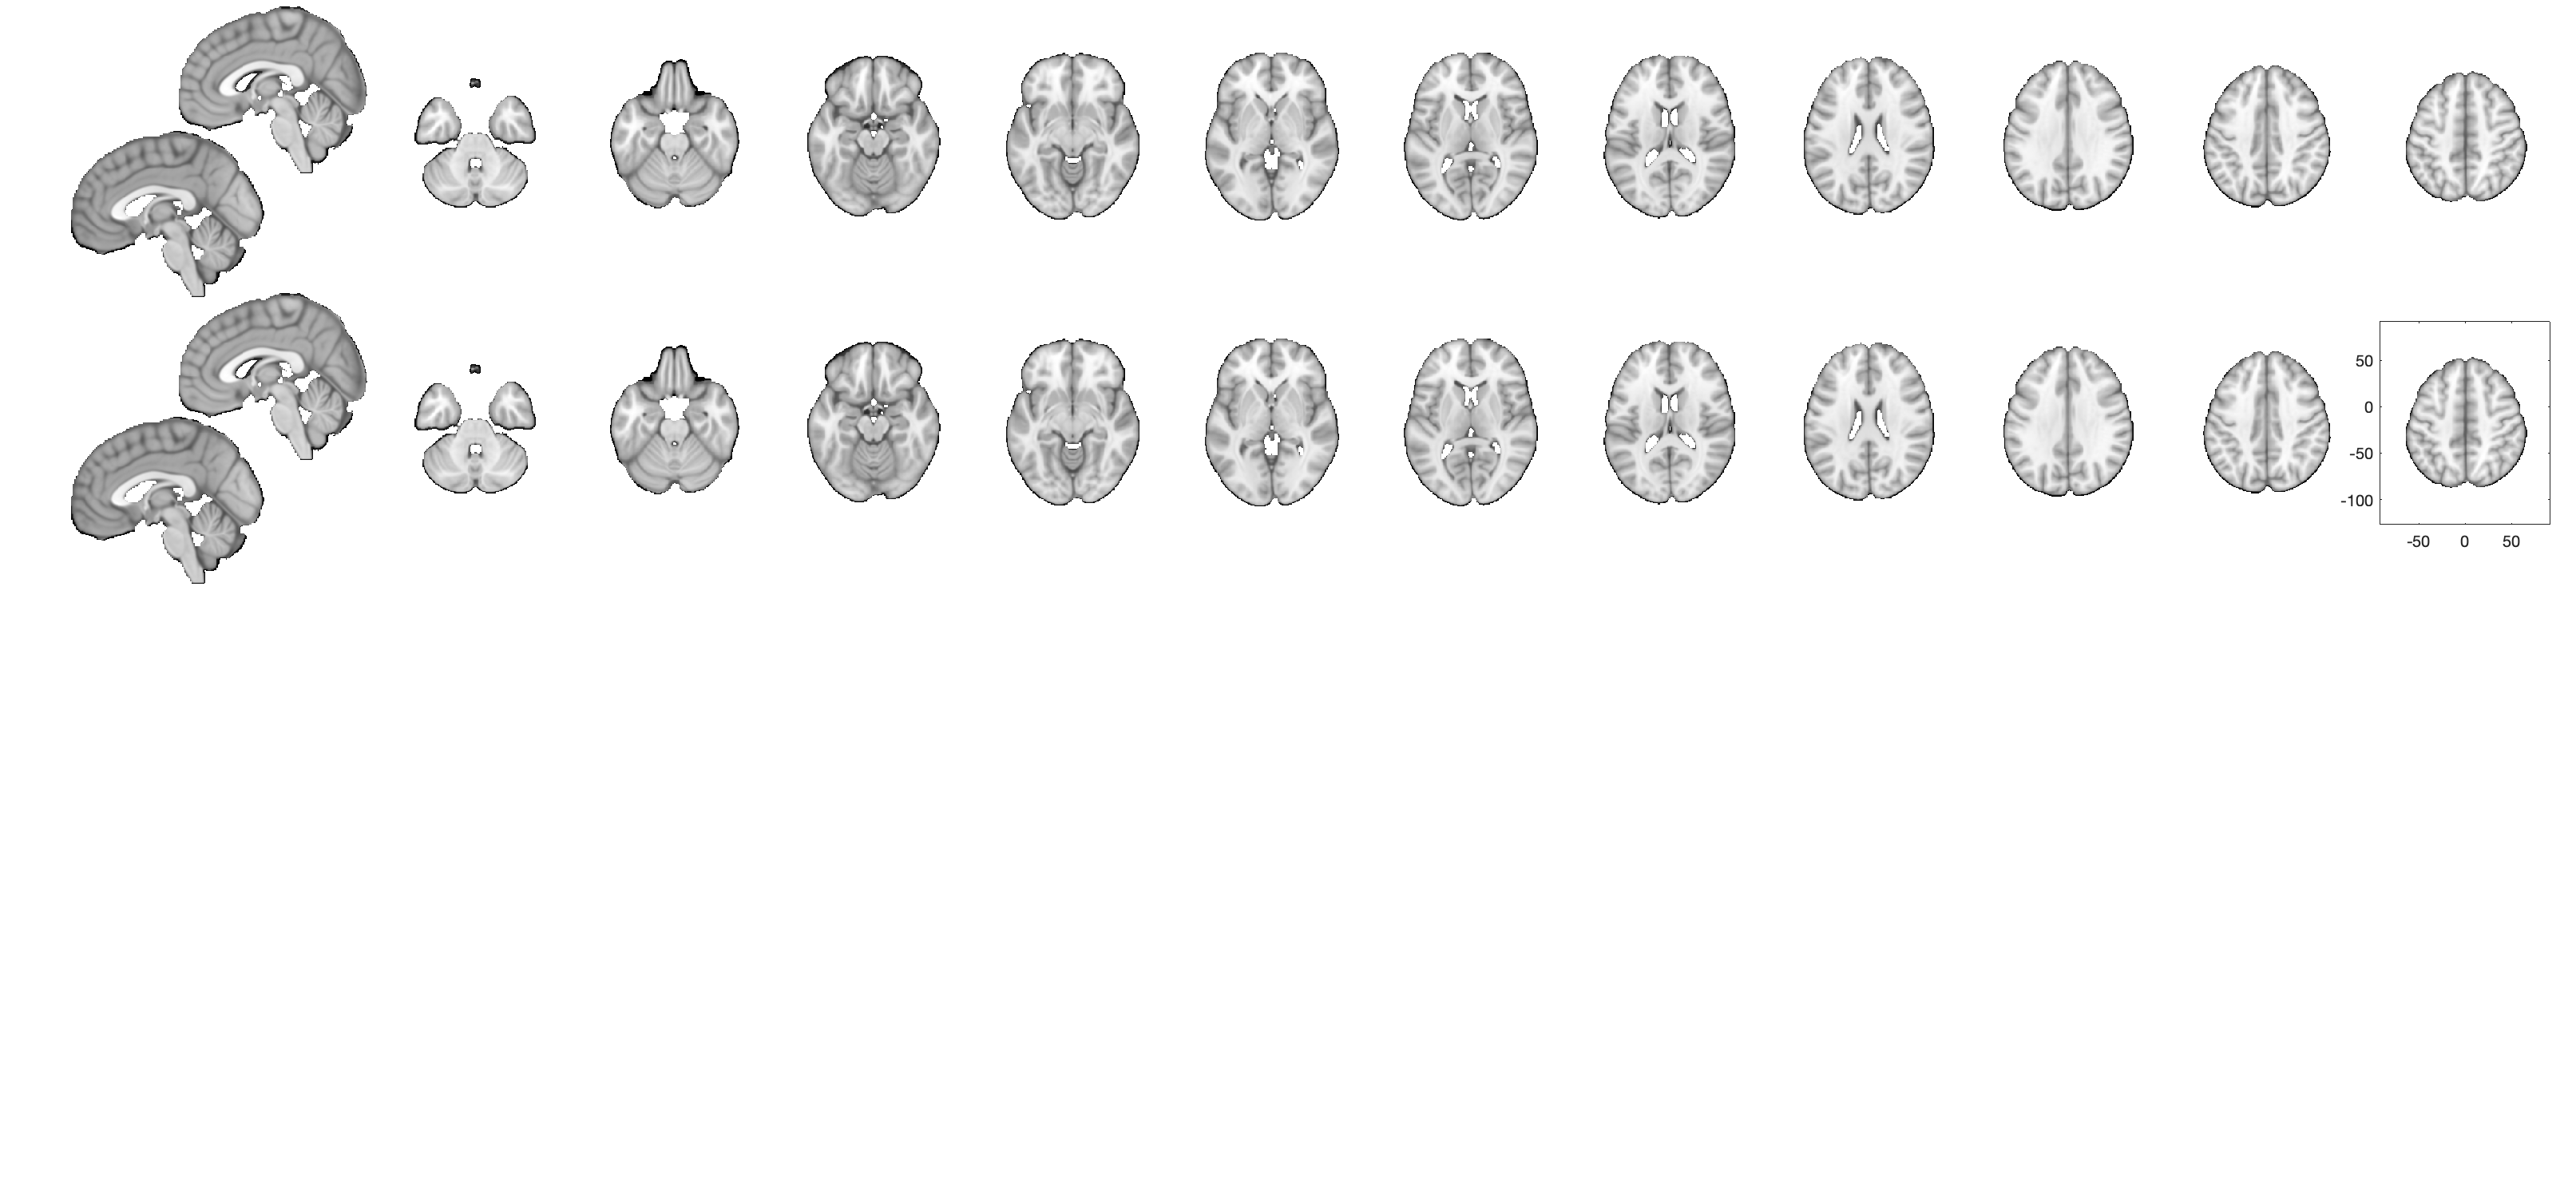

obj = rescale(obj, 'l2norm_images');
plot(obj)

obj.history(end+1) = {'Normalized each image by L2 norm'};

Look at an image with lots of negative values. It may have been Z-scored ahead of time.

obj1 = get_wh_image(obj, 32);
plot(obj1);
obj1 = remove_empty(obj1);
mean(obj1.dat)

## Summary

- 39 images. some dup transmitters

- Some are masked differently than others (e.g., gray matter mask applied). This will affect correlations among maps, because different maps have different voxels with valid values.

- Some are scaled differently than others (e.g., 32 possibly z-scored).  This won't affect correlations, but will affect any scale-dependent metric.  Best to re-scale images to a common scale and use relative metrics like correlation.

**To do:**

- Calculate sample size-weighted averages as in [https://github.com/netneurolab/hansen_receptors/blob/main/code/make_receptor_matrix.py](https://github.com/netneurolab/hansen_receptors/blob/main/code/make_receptor_matrix.py)

- Note: Justine Hansen uses z-scored maps to help sure maps on the same scale first!!

- Consider whether they dropped some maps due to coverage/masking? Also, if 0 (masked out) of one map and non-zero in another, don't take simple average.  use valid data... 

- Integrate with load_image_set so we can load with a keyword.

## Add meta-data

fname = fullfile(metadatadir, 'Table_S3.xlsx');
metadat = readtable(fname);

imagefilenames = cellstr(obj.image_names);
%  metadat.filename = imagefilenames;
size(metadat)
whos fname

% Figure out which are missing
% 13 (fazio) is not included in meta-data.  11-12 are reversed in order in
% metadata.
% 24 is not included.    {'FDOPA_fluorodopa_hc12_gomez.nii'      }
% 24-25 are reversed in order

% 28-30 are mGluR5 in metadata, not matched in images in this order
% Images 36-38 (after removing 14 and 24) go after 27.

% 33 {'NMDA_ge179_hc29_galovic.nii'          } does not have a match
% Spreng VAChT in metadata does not have a match

wh_images = ones(1, size(imagefilenames, 1));
wh_images([13 24 33]) = 0;
wh_images = find(wh_images);

wh_images = [wh_images([1:26]) wh_images([34:36]) wh_images([27:33])]


wh_images([4:5]) = wh_images([5:-1:4]);
wh_images([11:12]) = wh_images([12:-1:11]);
wh_images([23:24]) = wh_images([24:-1:23]);

wh_images([34 35 36]) = wh_images([35 36 34]);

% past this in to test
tmp = imagefilenames(wh_images)


% reorder images to match meta-data
obj = get_wh_image(obj, wh_images);

% remove Spreng (no match in images?)
metadat.primary_reference(34)
metadat(34, :) = []

% attach metadata
obj.metadata_table = metadat;


save Hansen_2022_PET_tracer_maps obj
